## **Soft Manipulator Actuation** 

We created a 0.9m soft beam with radius linearly varying from 3cm to 1cm. The link consists of 2 divisions, the first division is 0.4m long and the second is 0.5m long.

Torsion (x-axis) and bending (y- and z-axis) modes of deformation are enabled with a linear strain basis.

SorosimLink (`L1`) and SorosimLinkage (`T1`) are saved in `SoftManipulator.mat`

load('SoftManipulator.mat')

To see the properties of `L1`

L1

L1 =   SorosimLink with properties:

    jointtype: 'N'
     linktype: 's'
           CS: 'C'
         npie: 3
       nGauss: {[7]  [7]}
           Xs: {[7×1 double]  [7×1 double]}
           Ws: {[7×1 double]  [7×1 double]}
           lp: {[0.4000]  [0.5000]}
            L: 0.9000
            r: {@(X1)X1.*(-1.0./1.0e+2)+3.0./1.0e+2  @(X1)X1.*(-1.0./1.0e+2)+1.0./5.0e+1}
            h: {[]  []}
            w: {[]  []}
            a: {[]  []}
            b: {[]  []}
           gi: {[4×4 double]  [4×4 double]}
           gf: {[4×4 double]  [4×4 double]}
            E: 1000000
          Poi: 0.5000
            G: 3.3333e+05
          Eta: 11200
          Rho: 1000
           Kj: []
           Ms: {[42×6 double]  [42×6 double]}
           Es: {[42×6 double]  [42×6 double]}
           Gs: {[42×6 double]  [42×6 double]}
          n_l: 20
          n_r: 18
        color: [0.2238 0.7513 0.2551]


To see the properties of S`1`

T1

T1 =   SorosimLinkage with properties:

                   N: 1
                ndof: 12
                nsig: 15
              VLinks: [1×1 SorosimLink]
           LinkIndex: 1
            CVTwists: {[1×3 Twist]}
               iLpre: 0
               g_ini: [4×4 double]
             q_scale: [12×1 double]
                nCLj: 0
                iACL: []
                iCLB: []
          VTwistsCLj: []
               gACLj: []
               gBCLj: []
        CLprecompute: []
                T_BS: []
             Gravity: 0
                   G: 0
          PointForce: 0
       FollowerForce: []
                  np: []
              Fp_loc: []
              Fp_vec: []
                CEFP: 0
             M_added: [84×6 double]
            Actuated: 1
                nact: 4
                Bqj1: []
              n_jact: 0
              i_jact: []
             i_jactq: []
    WrenchControlled: []
              n_s

To see the problem definition:

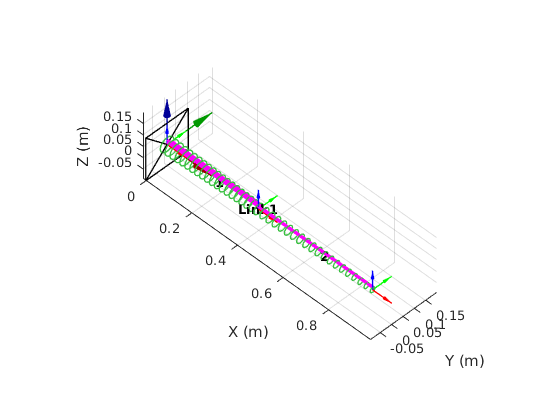

T1.plotq0

The result should be:

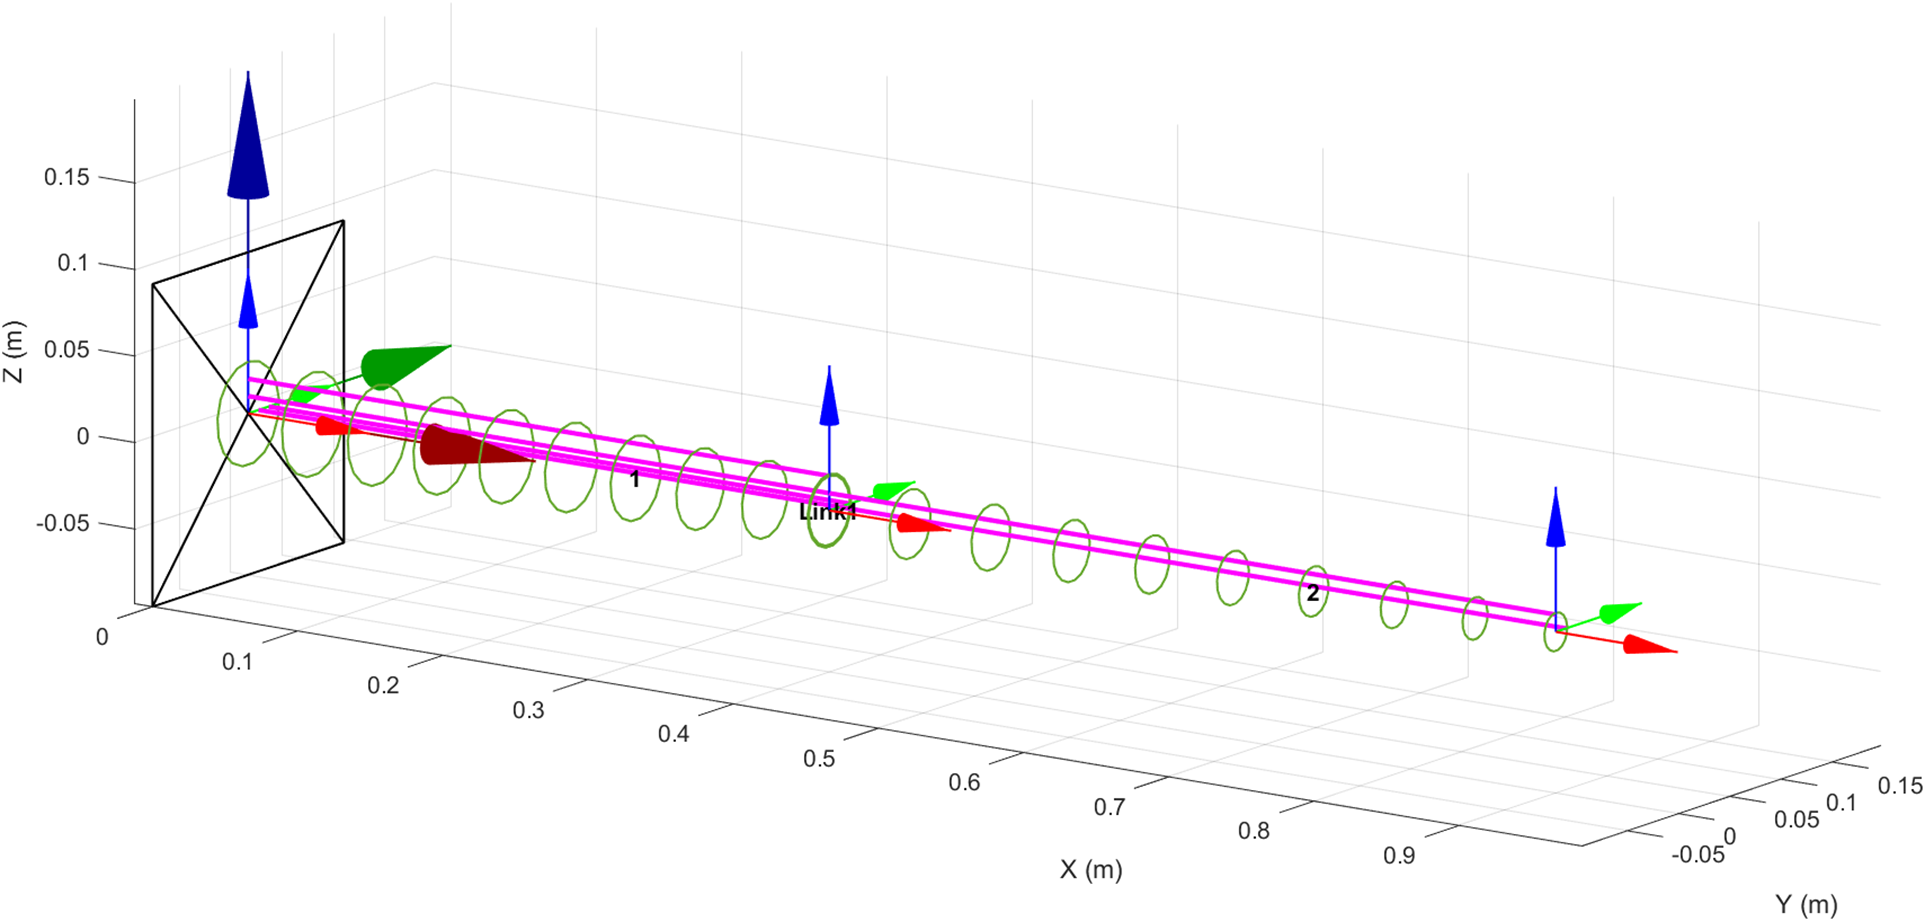

The beam is rigidly fixed at one end and can be subjected to actuation forces.

### **Static equilibirum analysis**

For statics equilibirum analysis type:

Time-advancing

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0         13      3.5625e+13                      3.93e+13               1
     1         26     6.38948e+12              1       2.01e+12               1
     2         39     9.59348e+11            2.5       5.94e+12             2.5
     3         52      0.00035395        5.82149       9.67e+04            6.25
     4         65     8.08891e-19    2.39793e-07         0.0046            14.6
     5         78     4.81482e-19    4.37146e-15         0.0046            14.6

Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the 

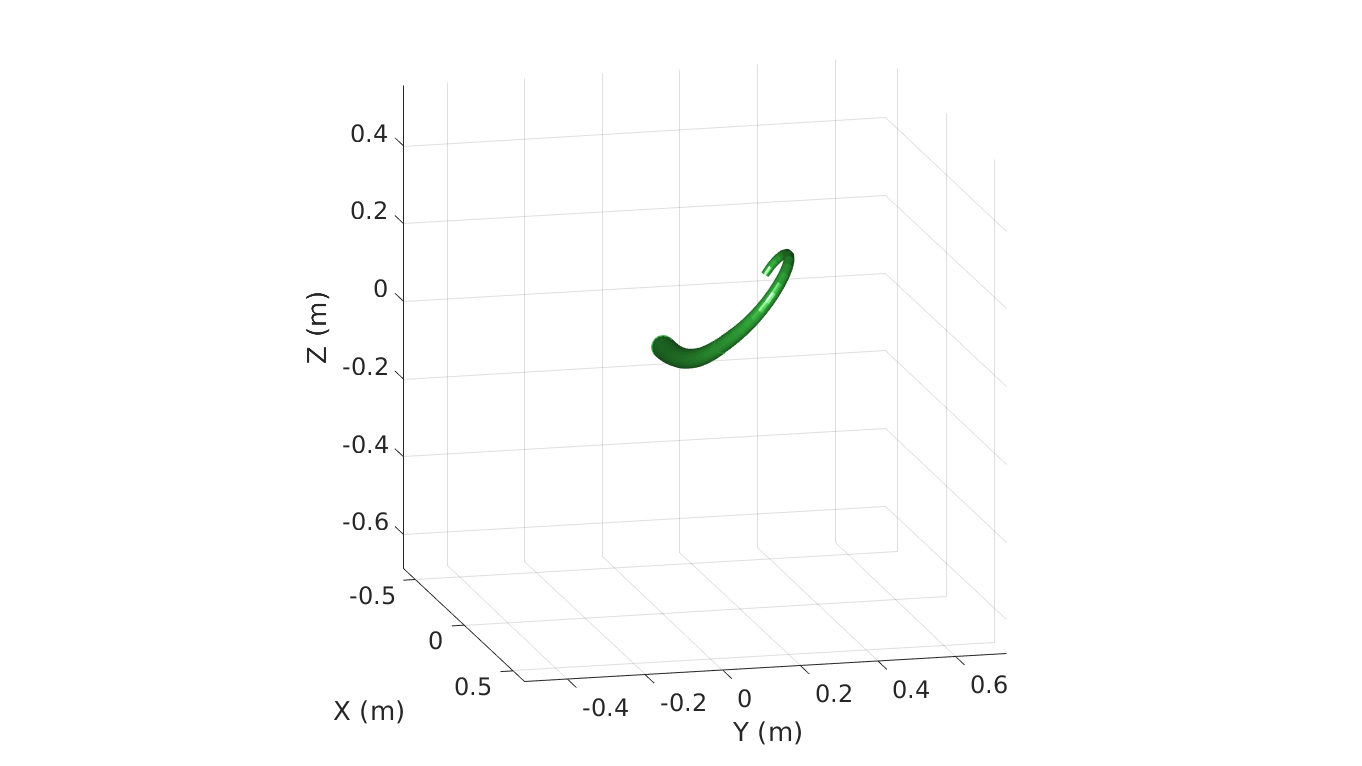

q=T1.statics;

You will be prompted to enter the actuation force in the command window. Enter -5, -10, -15, -20 N as the input actuation forces into cables 1, 2, 3 and 4 respectively. 

A dialog box will then pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

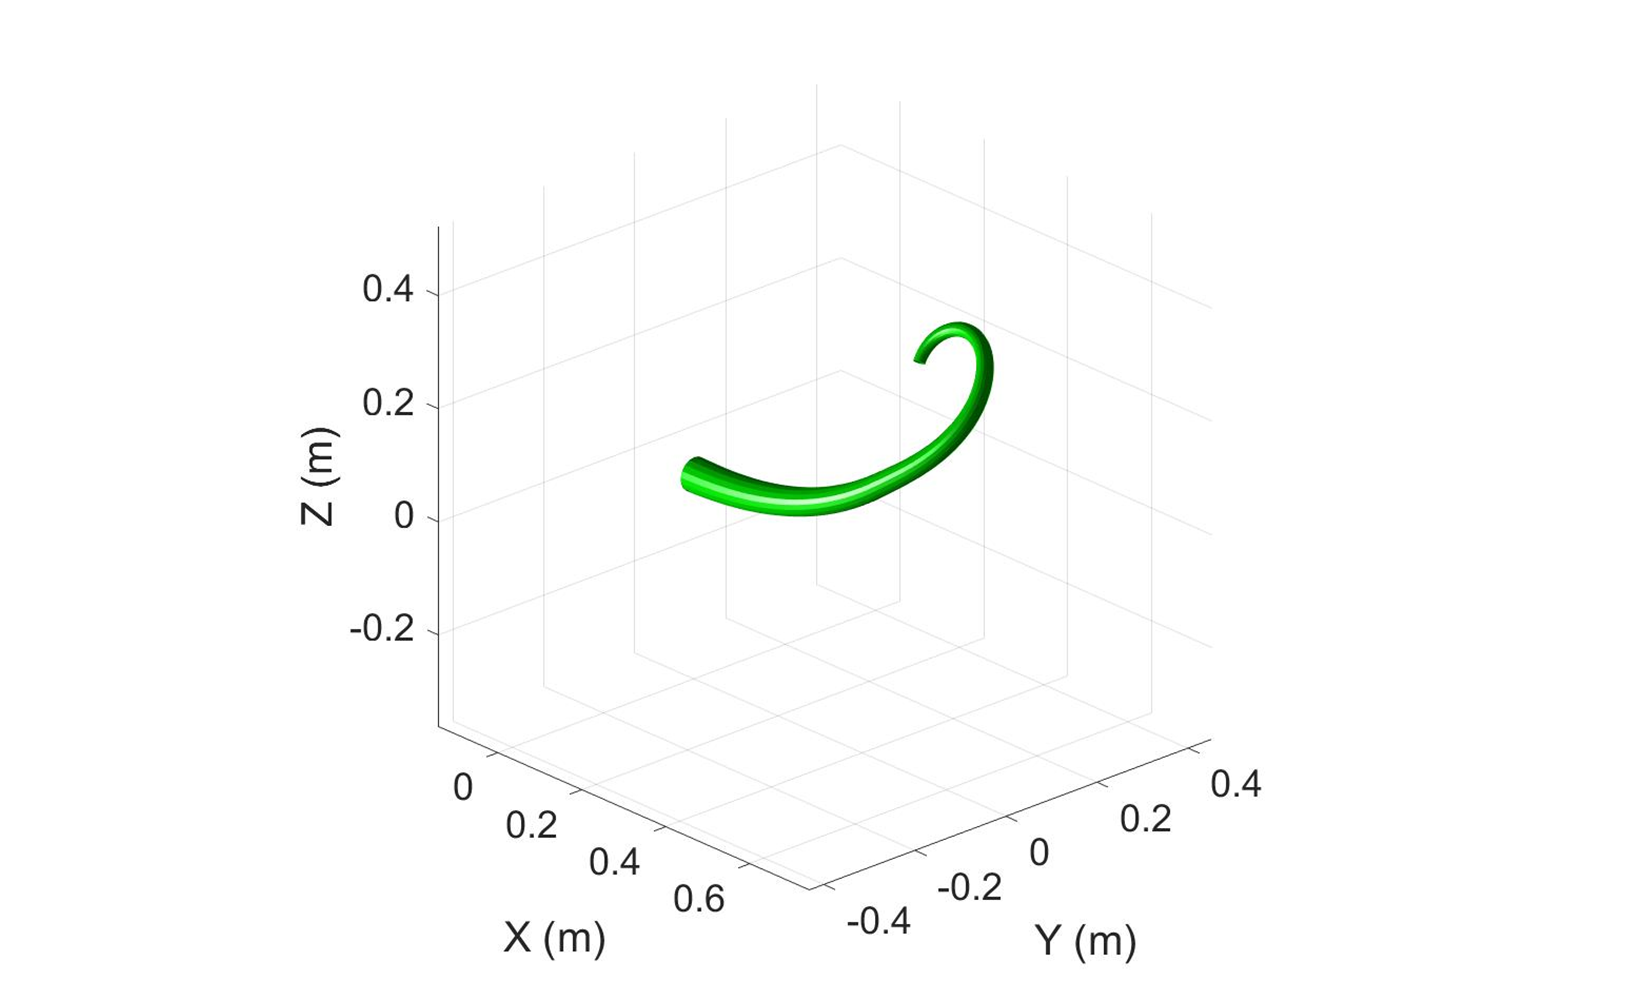

### **Dynamics**

For dynamics problem, type:

[t,qqd]=T1.dynamics;

Error using SorosimLinkage/dynamics (line 24)
Invalid use of operator.

The actuation input to the cables can be input by the user as a function of t in the command window.

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will then be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

Dynamic compulation will take some time.

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.avi` will be saved in the folder.